# Lab 1 Exercises 

## 1. Setup 

    1.1 Start Matlab 

    1.2 Download and install Peter Corke’s modified robotics toolbox (See UTSOnline) 

    1.3 Run the demos (type “rtbdemo”) to show the arms and get an idea what is possible.

## 2. Consider a car driving around a circular track

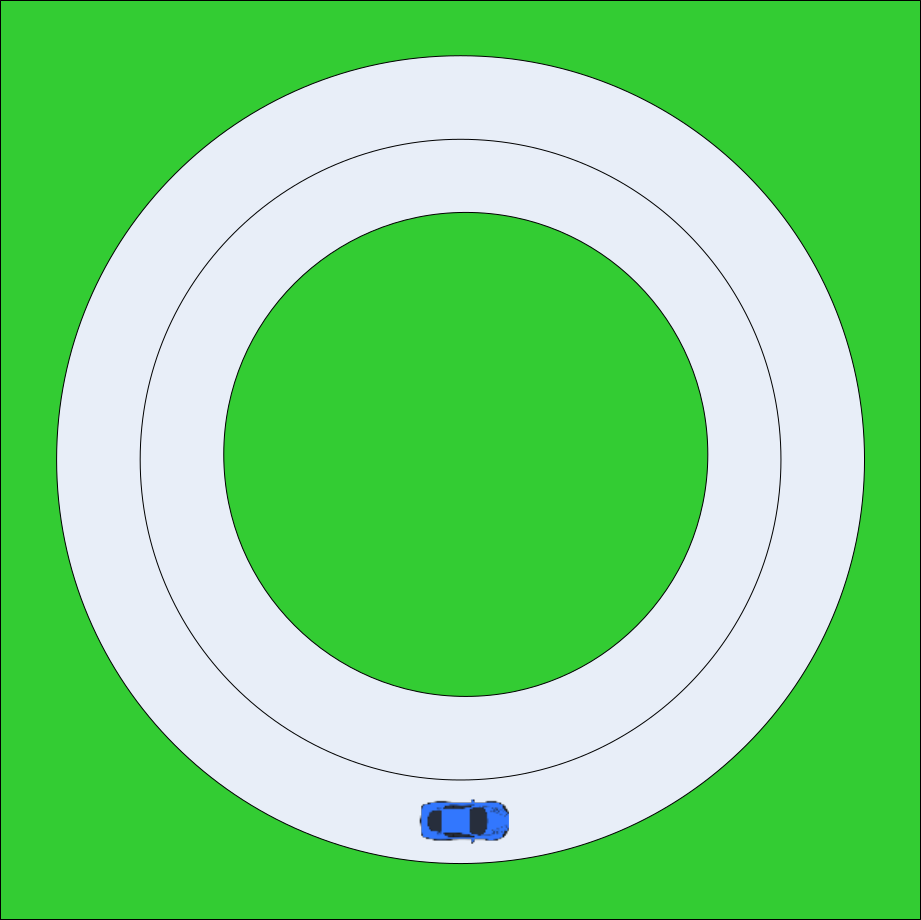

    2.1 Download the image from UTSOnline to file “W1LabEx1_CircularRaceTrack.jpg”, then open Matlab and Load the image with: 

set(gcf,'Name',['Question ',num2str(2)])
imshow('Lab1_CircularRaceTrack.jpg'); 
axis on
hold on

    2.2 Plot a transform representing the car at [300,550], use the ‘X’ axis of the transform to represent the heading of the car (note you will need to use “hold on” to show both)

T1 = se2(300, 550, 0)

T1 =      1     0   300
     0     1   550
     0     0     1


    2.3 Make the leg lengths of the transform 50 units long so it is visible on the track.

T1_h = trplot2(T1, 'frame', '1', 'color', 'b', 'length', 50);

    2.4 Now incrementally multiply the transform of the car by an offset transform and update the transform of the car

increments = 360

increments = 360

car1Move = se2(pi*480/increments,0,0)

car1Move =     1.0000         0    4.1888
         0    1.0000         0
         0         0    1.0000


car1Turn = se2(0,0,-2*pi/increments)

car1Turn =     0.9998    0.0175         0
   -0.0175    0.9998         0
         0         0    1.0000


for i=1:360
    T1 = T1 * car1Move * car1Turn
    try delete(T1_h);end
    T1_h = trplot2(T1, 'frame', '1', 'color', 'b', 'length', 50);
    drawnow();
end

T1 =     0.9998    0.0175  304.1888
   -0.0175    0.9998  550.0000
         0         0    1.0000


T1 =     0.9994    0.0349  308.3769
   -0.0349    0.9994  549.9269
         0         0    1.0000


T1 =     0.9986    0.0523  312.5632
   -0.0523    0.9986  549.7807
         0         0    1.0000


T1 =     0.9976    0.0698  316.7462
   -0.0698    0.9976  549.5615
         0         0    1.0000


T1 =     0.9962    0.0872  320.9248
   -0.0872    0.9962  549.2693
         0         0    1.0000


T1 =     0.9945    0.1045  325.0977
   -0.1045    0.9945  548.9042
         0         0    1.0000


T1 =     0.9925    0.1219  329.2635
   -0.1219    0.9925  548.4664
         0         0    1.0000


T1 =     0.9903    0.1392  333.4211
   -0.1392    0.9903  547.9559
         0         0    1.0000


T1 =     0.9877    0.1564  337.5691
   -0.1564    0.9877  547.3729
         0         0    1.0000


T1 =     0.9848    0.1736  341.7063
   -0.1736    0.9848  546.7176
         0         0    1.0000


T1 =     0.9816    0.1908  345.8315
   -0.1908    0.9816  545.9903
         0         0    1.0000


T1 =     0.9781    0.2079  349.9433
   -0.2079    0.9781  545.1910
         0         0    1.0000


T1 =     0.9744    0.2250  354.0406
   -0.2250    0.9744  544.3201
         0         0    1.0000


T1 =     0.9703    0.2419  358.1220
   -0.2419    0.9703  543.3778
         0         0    1.0000


T1 =     0.9659    0.2588  362.1864
   -0.2588    0.9659  542.3645
         0         0    1.0000


T1 =     0.9613    0.2756  366.2324
   -0.2756    0.9613  541.2803
         0         0    1.0000


T1 =     0.9563    0.2924  370.2589
   -0.2924    0.9563  540.1257
         0         0    1.0000


T1 =     0.9511    0.3090  374.2647
   -0.3090    0.9511  538.9011
         0         0    1.0000


T1 =     0.9455    0.3256  378.2485
   -0.3256    0.9455  537.6067
         0         0    1.0000


T1 =     0.9397    0.3420  382.2091
   -0.3420    0.9397  536.2429
         0         0    1.0000


T1 =     0.9336    0.3584  386.1452
   -0.3584    0.9336  534.8103
         0         0    1.0000


T1 =     0.9272    0.3746  390.0558
   -0.3746    0.9272  533.3091
         0         0    1.0000


T1 =     0.9205    0.3907  393.9396
   -0.3907    0.9205  531.7400
         0         0    1.0000


T1 =     0.9135    0.4067  397.7954
   -0.4067    0.9135  530.1033
         0         0    1.0000


T1 =     0.9063    0.4226  401.6220
   -0.4226    0.9063  528.3996
         0         0    1.0000


T1 =     0.8988    0.4384  405.4184
   -0.4384    0.8988  526.6293
         0         0    1.0000


T1 =     0.8910    0.4540  409.1832
   -0.4540    0.8910  524.7931
         0         0    1.0000


T1 =     0.8829    0.4695  412.9155
   -0.4695    0.8829  522.8914
         0         0    1.0000


T1 =     0.8746    0.4848  416.6140
   -0.4848    0.8746  520.9249
         0         0    1.0000


T1 =     0.8660    0.5000  420.2775
   -0.5000    0.8660  518.8941
         0         0    1.0000


T1 =     0.8572    0.5150  423.9051
   -0.5150    0.8572  516.7997
         0         0    1.0000


T1 =     0.8480    0.5299  427.4956
   -0.5299    0.8480  514.6423
         0         0    1.0000


T1 =     0.8387    0.5446  431.0479
   -0.5446    0.8387  512.4226
         0         0    1.0000


T1 =     0.8290    0.5592  434.5610
   -0.5592    0.8290  510.1412
         0         0    1.0000


T1 =     0.8192    0.5736  438.0336
   -0.5736    0.8192  507.7989
         0         0    1.0000


T1 =     0.8090    0.5878  441.4649
   -0.5878    0.8090  505.3963
         0         0    1.0000


T1 =     0.7986    0.6018  444.8537
   -0.6018    0.7986  502.9342
         0         0    1.0000


T1 =     0.7880    0.6157  448.1990
   -0.6157    0.7880  500.4133
         0         0    1.0000


T1 =     0.7771    0.6293  451.4998
   -0.6293    0.7771  497.8344
         0         0    1.0000


T1 =     0.7660    0.6428  454.7551
   -0.6428    0.7660  495.1983
         0         0    1.0000


T1 =     0.7547    0.6561  457.9639
   -0.6561    0.7547  492.5058
         0         0    1.0000


T1 =     0.7431    0.6691  461.1252
   -0.6691    0.7431  489.7577
         0         0    1.0000


T1 =     0.7314    0.6820  464.2381
   -0.6820    0.7314  486.9549
         0         0    1.0000


T1 =     0.7193    0.6947  467.3016
   -0.6947    0.7193  484.0982
         0         0    1.0000


T1 =     0.7071    0.7071  470.3148
   -0.7071    0.7071  481.1884
         0         0    1.0000


T1 =     0.6947    0.7193  473.2767
   -0.7193    0.6947  478.2265
         0         0    1.0000


T1 =     0.6820    0.7314  476.1865
   -0.7314    0.6820  475.2133
         0         0    1.0000


T1 = 3×3
    0.6691    0.7431  479.0432
   -0.7431    0.6691  472.1498
         0         0    1.0000


T1 = 3×3
    0.6561    0.7547  481.8460
   -0.7547    0.6561  469.0369
         0         0    1.0000


T1 = 3×3
    0.6428    0.7660  484.5941
   -0.7660    0.6428  465.8756
         0         0    1.0000


T1 = 3×3
    0.6293    0.7771  487.2866
   -0.7771    0.6293  462.6668
         0         0    1.0000


T1 = 3×3
    0.6157    0.7880  489.9227
   -0.7880    0.6157  459.4115
         0         0    1.0000


T1 = 3×3
    0.6018    0.7986  492.5016
   -0.7986    0.6018  456.1107
         0         0    1.0000


T1 = 3×3
    0.5878    0.8090  495.0225
   -0.8090    0.5878  452.7654
         0         0    1.0000


T1 = 3×3
    0.5736    0.8192  497.4846
   -0.8192    0.5736  449.3766
         0         0    1.0000


T1 = 3×3
    0.5592    0.8290  499.8872
   -0.8290    0.5592  445.9453
         0         0    1.0000


T1 = 3×3
    0.5446    0.8387  502.2295
   -0.8387    0.5446  442.4727
         0         0    1.0000


T1 = 3×3
    0.5299    0.8480  504.5109
   -0.8480    0.5299  438.9596
         0         0    1.0000


T1 = 3×3
    0.5150    0.8572  506.7306
   -0.8572    0.5150  435.4073
         0         0    1.0000


T1 = 3×3
    0.5000    0.8660  508.8880
   -0.8660    0.5000  431.8168
         0         0    1.0000


T1 = 3×3
    0.4848    0.8746  510.9824
   -0.8746    0.4848  428.1892
         0         0    1.0000


T1 = 3×3
    0.4695    0.8829  513.0132
   -0.8829    0.4695  424.5256
         0         0    1.0000


T1 = 3×3
    0.4540    0.8910  514.9797
   -0.8910    0.4540  420.8272
         0         0    1.0000


T1 = 3×3
    0.4384    0.8988  516.8814
   -0.8988    0.4384  417.0949
         0         0    1.0000


T1 = 3×3
    0.4226    0.9063  518.7176
   -0.9063    0.4226  413.3301
         0         0    1.0000


T1 = 3×3
    0.4067    0.9135  520.4879
   -0.9135    0.4067  409.5337
         0         0    1.0000


T1 = 3×3
    0.3907    0.9205  522.1916
   -0.9205    0.3907  405.7071
         0         0    1.0000


T1 = 3×3
    0.3746    0.9272  523.8283
   -0.9272    0.3746  401.8513
         0         0    1.0000


T1 = 3×3
    0.3584    0.9336  525.3974
   -0.9336    0.3584  397.9675
         0         0    1.0000


T1 = 3×3
    0.3420    0.9397  526.8986
   -0.9397    0.3420  394.0569
         0         0    1.0000


T1 = 3×3
    0.3256    0.9455  528.3312
   -0.9455    0.3256  390.1208
         0         0    1.0000


T1 = 3×3
    0.3090    0.9511  529.6950
   -0.9511    0.3090  386.1602
         0         0    1.0000


T1 = 3×3
    0.2924    0.9563  530.9894
   -0.9563    0.2924  382.1764
         0         0    1.0000


T1 = 3×3
    0.2756    0.9613  532.2141
   -0.9613    0.2756  378.1706
         0         0    1.0000


T1 = 3×3
    0.2588    0.9659  533.3686
   -0.9659    0.2588  374.1441
         0         0    1.0000


T1 = 3×3
    0.2419    0.9703  534.4528
   -0.9703    0.2419  370.0981
         0         0    1.0000


T1 = 3×3
    0.2250    0.9744  535.4661
   -0.9744    0.2250  366.0337
         0         0    1.0000


T1 = 3×3
    0.2079    0.9781  536.4084
   -0.9781    0.2079  361.9523
         0         0    1.0000


T1 = 3×3
    0.1908    0.9816  537.2793
   -0.9816    0.1908  357.8550
         0         0    1.0000


T1 = 3×3
    0.1736    0.9848  538.0786
   -0.9848    0.1736  353.7432
         0         0    1.0000


T1 = 3×3
    0.1564    0.9877  538.8059
   -0.9877    0.1564  349.6180
         0         0    1.0000


T1 = 3×3
    0.1392    0.9903  539.4612
   -0.9903    0.1392  345.4808
         0         0    1.0000


T1 = 3×3
    0.1219    0.9925  540.0442
   -0.9925    0.1219  341.3328
         0         0    1.0000


T1 = 3×3
    0.1045    0.9945  540.5547
   -0.9945    0.1045  337.1752
         0         0    1.0000


T1 = 3×3
    0.0872    0.9962  540.9925
   -0.9962    0.0872  333.0094
         0         0    1.0000


T1 = 3×3
    0.0698    0.9976  541.3576
   -0.9976    0.0698  328.8365
         0         0    1.0000


T1 = 3×3
    0.0523    0.9986  541.6498
   -0.9986    0.0523  324.6579
         0         0    1.0000


T1 = 3×3
    0.0349    0.9994  541.8690
   -0.9994    0.0349  320.4749
         0         0    1.0000


T1 = 3×3
    0.0175    0.9998  542.0152
   -0.9998    0.0175  316.2886
         0         0    1.0000


T1 = 3×3
    0.0000    1.0000  542.0883
   -1.0000    0.0000  312.1005
         0         0    1.0000


T1 = 3×3
   -0.0175    0.9998  542.0883
   -0.9998   -0.0175  307.9117
         0         0    1.0000


T1 = 3×3
   -0.0349    0.9994  542.0152
   -0.9994   -0.0349  303.7235
         0         0    1.0000


T1 = 3×3
   -0.0523    0.9986  541.8690
   -0.9986   -0.0523  299.5373
         0         0    1.0000


T1 = 3×3
   -0.0698    0.9976  541.6498
   -0.9976   -0.0698  295.3543
         0         0    1.0000


T1 = 3×3
   -0.0872    0.9962  541.3576
   -0.9962   -0.0872  291.1757
         0         0    1.0000


T1 = 3×3
   -0.1045    0.9945  540.9925
   -0.9945   -0.1045  287.0028
         0         0    1.0000


T1 = 3×3
   -0.1219    0.9925  540.5547
   -0.9925   -0.1219  282.8370
         0         0    1.0000


T1 = 3×3
   -0.1392    0.9903  540.0442
   -0.9903   -0.1392  278.6794
         0         0    1.0000


T1 = 3×3
   -0.1564    0.9877  539.4612
   -0.9877   -0.1564  274.5314
         0         0    1.0000


T1 = 3×3
   -0.1736    0.9848  538.8059
   -0.9848   -0.1736  270.3942
         0         0    1.0000


T1 = 3×3
   -0.1908    0.9816  538.0786
   -0.9816   -0.1908  266.2690
         0         0    1.0000


T1 = 3×3
   -0.2079    0.9781  537.2793
   -0.9781   -0.2079  262.1572
         0         0    1.0000


T1 = 3×3
   -0.2250    0.9744  536.4084
   -0.9744   -0.2250  258.0599
         0         0    1.0000


T1 = 3×3
   -0.2419    0.9703  535.4661
   -0.9703   -0.2419  253.9785
         0         0    1.0000


T1 = 3×3
   -0.2588    0.9659  534.4528
   -0.9659   -0.2588  249.9141
         0         0    1.0000


T1 = 3×3
   -0.2756    0.9613  533.3686
   -0.9613   -0.2756  245.8681
         0         0    1.0000


T1 = 3×3
   -0.2924    0.9563  532.2141
   -0.9563   -0.2924  241.8415
         0         0    1.0000


T1 = 3×3
   -0.3090    0.9511  530.9894
   -0.9511   -0.3090  237.8358
         0         0    1.0000


T1 = 3×3
   -0.3256    0.9455  529.6950
   -0.9455   -0.3256  233.8520
         0         0    1.0000


T1 = 3×3
   -0.3420    0.9397  528.3312
   -0.9397   -0.3420  229.8914
         0         0    1.0000


T1 = 3×3
   -0.3584    0.9336  526.8986
   -0.9336   -0.3584  225.9553
         0         0    1.0000


T1 = 3×3
   -0.3746    0.9272  525.3974
   -0.9272   -0.3746  222.0447
         0         0    1.0000


T1 = 3×3
   -0.3907    0.9205  523.8283
   -0.9205   -0.3907  218.1609
         0         0    1.0000


T1 = 3×3
   -0.4067    0.9135  522.1916
   -0.9135   -0.4067  214.3051
         0         0    1.0000


T1 = 3×3
   -0.4226    0.9063  520.4879
   -0.9063   -0.4226  210.4785
         0         0    1.0000


T1 = 3×3
   -0.4384    0.8988  518.7176
   -0.8988   -0.4384  206.6821
         0         0    1.0000


T1 = 3×3
   -0.4540    0.8910  516.8814
   -0.8910   -0.4540  202.9173
         0         0    1.0000


T1 = 3×3
   -0.4695    0.8829  514.9797
   -0.8829   -0.4695  199.1850
         0         0    1.0000


T1 = 3×3
   -0.4848    0.8746  513.0132
   -0.8746   -0.4848  195.4865
         0         0    1.0000


T1 = 3×3
   -0.5000    0.8660  510.9824
   -0.8660   -0.5000  191.8229
         0         0    1.0000


T1 = 3×3
   -0.5150    0.8572  508.8880
   -0.8572   -0.5150  188.1953
         0         0    1.0000


T1 = 3×3
   -0.5299    0.8480  506.7306
   -0.8480   -0.5299  184.6048
         0         0    1.0000


T1 = 3×3
   -0.5446    0.8387  504.5109
   -0.8387   -0.5446  181.0525
         0         0    1.0000


T1 = 3×3
   -0.5592    0.8290  502.2295
   -0.8290   -0.5592  177.5395
         0         0    1.0000


T1 = 3×3
   -0.5736    0.8192  499.8872
   -0.8192   -0.5736  174.0669
         0         0    1.0000


T1 = 3×3
   -0.5878    0.8090  497.4846
   -0.8090   -0.5878  170.6356
         0         0    1.0000


T1 = 3×3
   -0.6018    0.7986  495.0225
   -0.7986   -0.6018  167.2468
         0         0    1.0000


T1 = 3×3
   -0.6157    0.7880  492.5016
   -0.7880   -0.6157  163.9015
         0         0    1.0000


T1 = 3×3
   -0.6293    0.7771  489.9227
   -0.7771   -0.6293  160.6007
         0         0    1.0000


T1 = 3×3
   -0.6428    0.7660  487.2866
   -0.7660   -0.6428  157.3454
         0         0    1.0000


T1 = 3×3
   -0.6561    0.7547  484.5941
   -0.7547   -0.6561  154.1366
         0         0    1.0000


T1 = 3×3
   -0.6691    0.7431  481.8460
   -0.7431   -0.6691  150.9753
         0         0    1.0000


T1 = 3×3
   -0.6820    0.7314  479.0432
   -0.7314   -0.6820  147.8624
         0         0    1.0000


T1 = 3×3
   -0.6947    0.7193  476.1865
   -0.7193   -0.6947  144.7989
         0         0    1.0000


T1 = 3×3
   -0.7071    0.7071  473.2767
   -0.7071   -0.7071  141.7857
         0         0    1.0000


T1 = 3×3
   -0.7193    0.6947  470.3148
   -0.6947   -0.7193  138.8238
         0         0    1.0000


T1 = 3×3
   -0.7314    0.6820  467.3016
   -0.6820   -0.7314  135.9140
         0         0    1.0000


T1 = 3×3
   -0.7431    0.6691  464.2381
   -0.6691   -0.7431  133.0573
         0         0    1.0000


T1 = 3×3
   -0.7547    0.6561  461.1252
   -0.6561   -0.7547  130.2544
         0         0    1.0000


T1 = 3×3
   -0.7660    0.6428  457.9639
   -0.6428   -0.7660  127.5063
         0         0    1.0000


T1 = 3×3
   -0.7771    0.6293  454.7551
   -0.6293   -0.7771  124.8138
         0         0    1.0000


T1 = 3×3
   -0.7880    0.6157  451.4998
   -0.6157   -0.7880  122.1778
         0         0    1.0000


T1 = 3×3
   -0.7986    0.6018  448.1990
   -0.6018   -0.7986  119.5989
         0         0    1.0000


T1 = 3×3
   -0.8090    0.5878  444.8537
   -0.5878   -0.8090  117.0780
         0         0    1.0000


T1 = 3×3
   -0.8192    0.5736  441.4649
   -0.5736   -0.8192  114.6159
         0         0    1.0000


T1 = 3×3
   -0.8290    0.5592  438.0336
   -0.5592   -0.8290  112.2133
         0         0    1.0000


T1 = 3×3
   -0.8387    0.5446  434.5610
   -0.5446   -0.8387  109.8710
         0         0    1.0000


T1 = 3×3
   -0.8480    0.5299  431.0479
   -0.5299   -0.8480  107.5896
         0         0    1.0000


T1 = 3×3
   -0.8572    0.5150  427.4956
   -0.5150   -0.8572  105.3699
         0         0    1.0000


T1 = 3×3
   -0.8660    0.5000  423.9051
   -0.5000   -0.8660  103.2125
         0         0    1.0000


T1 = 3×3
   -0.8746    0.4848  420.2775
   -0.4848   -0.8746  101.1181
         0         0    1.0000


T1 = 3×3
   -0.8829    0.4695  416.6140
   -0.4695   -0.8829   99.0873
         0         0    1.0000


T1 = 3×3
   -0.8910    0.4540  412.9155
   -0.4540   -0.8910   97.1208
         0         0    1.0000


T1 = 3×3
   -0.8988    0.4384  409.1832
   -0.4384   -0.8988   95.2191
         0         0    1.0000


T1 = 3×3
   -0.9063    0.4226  405.4184
   -0.4226   -0.9063   93.3829
         0         0    1.0000


T1 = 3×3
   -0.9135    0.4067  401.6220
   -0.4067   -0.9135   91.6126
         0         0    1.0000


T1 = 3×3
   -0.9205    0.3907  397.7954
   -0.3907   -0.9205   89.9089
         0         0    1.0000


T1 = 3×3
   -0.9272    0.3746  393.9396
   -0.3746   -0.9272   88.2722
         0         0    1.0000


T1 = 3×3
   -0.9336    0.3584  390.0558
   -0.3584   -0.9336   86.7030
         0         0    1.0000


T1 = 3×3
   -0.9397    0.3420  386.1452
   -0.3420   -0.9397   85.2019
         0         0    1.0000


T1 = 3×3
   -0.9455    0.3256  382.2091
   -0.3256   -0.9455   83.7693
         0         0    1.0000


T1 = 3×3
   -0.9511    0.3090  378.2485
   -0.3090   -0.9511   82.4055
         0         0    1.0000


T1 = 3×3
   -0.9563    0.2924  374.2647
   -0.2924   -0.9563   81.1111
         0         0    1.0000


T1 = 3×3
   -0.9613    0.2756  370.2589
   -0.2756   -0.9613   79.8864
         0         0    1.0000


T1 = 3×3
   -0.9659    0.2588  366.2324
   -0.2588   -0.9659   78.7318
         0         0    1.0000


T1 = 3×3
   -0.9703    0.2419  362.1864
   -0.2419   -0.9703   77.6477
         0         0    1.0000


T1 = 3×3
   -0.9744    0.2250  358.1220
   -0.2250   -0.9744   76.6343
         0         0    1.0000


T1 = 3×3
   -0.9781    0.2079  354.0406
   -0.2079   -0.9781   75.6921
         0         0    1.0000


T1 = 3×3
   -0.9816    0.1908  349.9433
   -0.1908   -0.9816   74.8212
         0         0    1.0000


T1 = 3×3
   -0.9848    0.1736  345.8315
   -0.1736   -0.9848   74.0219
         0         0    1.0000


T1 = 3×3
   -0.9877    0.1564  341.7063
   -0.1564   -0.9877   73.2945
         0         0    1.0000


T1 = 3×3
   -0.9903    0.1392  337.5691
   -0.1392   -0.9903   72.6393
         0         0    1.0000


T1 = 3×3
   -0.9925    0.1219  333.4211
   -0.1219   -0.9925   72.0563
         0         0    1.0000


T1 = 3×3
   -0.9945    0.1045  329.2635
   -0.1045   -0.9945   71.5458
         0         0    1.0000


T1 = 3×3
   -0.9962    0.0872  325.0977
   -0.0872   -0.9962   71.1080
         0         0    1.0000


T1 = 3×3
   -0.9976    0.0698  320.9248
   -0.0698   -0.9976   70.7429
         0         0    1.0000


T1 = 3×3
   -0.9986    0.0523  316.7462
   -0.0523   -0.9986   70.4507
         0         0    1.0000


T1 = 3×3
   -0.9994    0.0349  312.5632
   -0.0349   -0.9994   70.2315
         0         0    1.0000


T1 = 3×3
   -0.9998    0.0175  308.3769
   -0.0175   -0.9998   70.0853
         0         0    1.0000


T1 = 3×3
   -1.0000    0.0000  304.1888
   -0.0000   -1.0000   70.0122
         0         0    1.0000


T1 = 3×3
   -0.9998   -0.0175  300.0000
    0.0175   -0.9998   70.0122
         0         0    1.0000


T1 = 3×3
   -0.9994   -0.0349  295.8118
    0.0349   -0.9994   70.0853
         0         0    1.0000


T1 = 3×3
   -0.9986   -0.0523  291.6256
    0.0523   -0.9986   70.2315
         0         0    1.0000


T1 = 3×3
   -0.9976   -0.0698  287.4426
    0.0698   -0.9976   70.4507
         0         0    1.0000


T1 = 3×3
   -0.9962   -0.0872  283.2640
    0.0872   -0.9962   70.7429
         0         0    1.0000


T1 = 3×3
   -0.9945   -0.1045  279.0911
    0.1045   -0.9945   71.1080
         0         0    1.0000


T1 = 3×3
   -0.9925   -0.1219  274.9253
    0.1219   -0.9925   71.5458
         0         0    1.0000


T1 = 3×3
   -0.9903   -0.1392  270.7677
    0.1392   -0.9903   72.0563
         0         0    1.0000


T1 = 3×3
   -0.9877   -0.1564  266.6197
    0.1564   -0.9877   72.6393
         0         0    1.0000


T1 = 3×3
   -0.9848   -0.1736  262.4825
    0.1736   -0.9848   73.2945
         0         0    1.0000


T1 = 3×3
   -0.9816   -0.1908  258.3573
    0.1908   -0.9816   74.0219
         0         0    1.0000


T1 = 3×3
   -0.9781   -0.2079  254.2455
    0.2079   -0.9781   74.8212
         0         0    1.0000


T1 = 3×3
   -0.9744   -0.2250  250.1482
    0.2250   -0.9744   75.6921
         0         0    1.0000


T1 = 3×3
   -0.9703   -0.2419  246.0668
    0.2419   -0.9703   76.6343
         0         0    1.0000


T1 = 3×3
   -0.9659   -0.2588  242.0024
    0.2588   -0.9659   77.6477
         0         0    1.0000


T1 = 3×3
   -0.9613   -0.2756  237.9564
    0.2756   -0.9613   78.7318
         0         0    1.0000


T1 = 3×3
   -0.9563   -0.2924  233.9298
    0.2924   -0.9563   79.8864
         0         0    1.0000


T1 = 3×3
   -0.9511   -0.3090  229.9241
    0.3090   -0.9511   81.1111
         0         0    1.0000


T1 = 3×3
   -0.9455   -0.3256  225.9403
    0.3256   -0.9455   82.4055
         0         0    1.0000


T1 = 3×3
   -0.9397   -0.3420  221.9797
    0.3420   -0.9397   83.7693
         0         0    1.0000


T1 = 3×3
   -0.9336   -0.3584  218.0436
    0.3584   -0.9336   85.2019
         0         0    1.0000


T1 = 3×3
   -0.9272   -0.3746  214.1330
    0.3746   -0.9272   86.7030
         0         0    1.0000


T1 = 3×3
   -0.9205   -0.3907  210.2492
    0.3907   -0.9205   88.2722
         0         0    1.0000


T1 = 3×3
   -0.9135   -0.4067  206.3934
    0.4067   -0.9135   89.9089
         0         0    1.0000


T1 = 3×3
   -0.9063   -0.4226  202.5668
    0.4226   -0.9063   91.6126
         0         0    1.0000


T1 = 3×3
   -0.8988   -0.4384  198.7704
    0.4384   -0.8988   93.3829
         0         0    1.0000


T1 = 3×3
   -0.8910   -0.4540  195.0056
    0.4540   -0.8910   95.2191
         0         0    1.0000


T1 = 3×3
   -0.8829   -0.4695  191.2733
    0.4695   -0.8829   97.1208
         0         0    1.0000


T1 = 3×3
   -0.8746   -0.4848  187.5748
    0.4848   -0.8746   99.0873
         0         0    1.0000


T1 = 3×3
   -0.8660   -0.5000  183.9112
    0.5000   -0.8660  101.1181
         0         0    1.0000


T1 = 3×3
   -0.8572   -0.5150  180.2836
    0.5150   -0.8572  103.2125
         0         0    1.0000


T1 = 3×3
   -0.8480   -0.5299  176.6931
    0.5299   -0.8480  105.3699
         0         0    1.0000


T1 = 3×3
   -0.8387   -0.5446  173.1409
    0.5446   -0.8387  107.5896
         0         0    1.0000


T1 = 3×3
   -0.8290   -0.5592  169.6278
    0.5592   -0.8290  109.8710
         0         0    1.0000


T1 = 3×3
   -0.8192   -0.5736  166.1552
    0.5736   -0.8192  112.2133
         0         0    1.0000


T1 = 3×3
   -0.8090   -0.5878  162.7239
    0.5878   -0.8090  114.6159
         0         0    1.0000


T1 = 3×3
   -0.7986   -0.6018  159.3351
    0.6018   -0.7986  117.0780
         0         0    1.0000


T1 = 3×3
   -0.7880   -0.6157  155.9898
    0.6157   -0.7880  119.5989
         0         0    1.0000


T1 = 3×3
   -0.7771   -0.6293  152.6890
    0.6293   -0.7771  122.1778
         0         0    1.0000


T1 = 3×3
   -0.7660   -0.6428  149.4337
    0.6428   -0.7660  124.8138
         0         0    1.0000


T1 = 3×3
   -0.7547   -0.6561  146.2249
    0.6561   -0.7547  127.5063
         0         0    1.0000


T1 = 3×3
   -0.7431   -0.6691  143.0636
    0.6691   -0.7431  130.2544
         0         0    1.0000


T1 = 3×3
   -0.7314   -0.6820  139.9507
    0.6820   -0.7314  133.0573
         0         0    1.0000


T1 = 3×3
   -0.7193   -0.6947  136.8872
    0.6947   -0.7193  135.9140
         0         0    1.0000


T1 = 3×3
   -0.7071   -0.7071  133.8740
    0.7071   -0.7071  138.8238
         0         0    1.0000


T1 = 3×3
   -0.6947   -0.7193  130.9121
    0.7193   -0.6947  141.7857
         0         0    1.0000


T1 = 3×3
   -0.6820   -0.7314  128.0023
    0.7314   -0.6820  144.7989
         0         0    1.0000


T1 = 3×3
   -0.6691   -0.7431  125.1456
    0.7431   -0.6691  147.8624
         0         0    1.0000


T1 = 3×3
   -0.6561   -0.7547  122.3427
    0.7547   -0.6561  150.9753
         0         0    1.0000


T1 = 3×3
   -0.6428   -0.7660  119.5946
    0.7660   -0.6428  154.1366
         0         0    1.0000


T1 = 3×3
   -0.6293   -0.7771  116.9021
    0.7771   -0.6293  157.3454
         0         0    1.0000


T1 = 3×3
   -0.6157   -0.7880  114.2661
    0.7880   -0.6157  160.6007
         0         0    1.0000


T1 = 3×3
   -0.6018   -0.7986  111.6872
    0.7986   -0.6018  163.9015
         0         0    1.0000


T1 = 3×3
   -0.5878   -0.8090  109.1663
    0.8090   -0.5878  167.2468
         0         0    1.0000


T1 = 3×3
   -0.5736   -0.8192  106.7042
    0.8192   -0.5736  170.6356
         0         0    1.0000


T1 = 3×3
   -0.5592   -0.8290  104.3016
    0.8290   -0.5592  174.0669
         0         0    1.0000


T1 = 3×3
   -0.5446   -0.8387  101.9593
    0.8387   -0.5446  177.5395
         0         0    1.0000


T1 = 3×3
   -0.5299   -0.8480   99.6779
    0.8480   -0.5299  181.0525
         0         0    1.0000


T1 = 3×3
   -0.5150   -0.8572   97.4582
    0.8572   -0.5150  184.6048
         0         0    1.0000


T1 = 3×3
   -0.5000   -0.8660   95.3008
    0.8660   -0.5000  188.1953
         0         0    1.0000


T1 = 3×3
   -0.4848   -0.8746   93.2064
    0.8746   -0.4848  191.8229
         0         0    1.0000


T1 = 3×3
   -0.4695   -0.8829   91.1756
    0.8829   -0.4695  195.4865
         0         0    1.0000


T1 = 3×3
   -0.4540   -0.8910   89.2091
    0.8910   -0.4540  199.1850
         0         0    1.0000


T1 = 3×3
   -0.4384   -0.8988   87.3074
    0.8988   -0.4384  202.9173
         0         0    1.0000


T1 = 3×3
   -0.4226   -0.9063   85.4712
    0.9063   -0.4226  206.6821
         0         0    1.0000


T1 = 3×3
   -0.4067   -0.9135   83.7009
    0.9135   -0.4067  210.4785
         0         0    1.0000


T1 = 3×3
   -0.3907   -0.9205   81.9972
    0.9205   -0.3907  214.3051
         0         0    1.0000


T1 = 3×3
   -0.3746   -0.9272   80.3605
    0.9272   -0.3746  218.1609
         0         0    1.0000


T1 = 3×3
   -0.3584   -0.9336   78.7913
    0.9336   -0.3584  222.0447
         0         0    1.0000


T1 = 3×3
   -0.3420   -0.9397   77.2902
    0.9397   -0.3420  225.9553
         0         0    1.0000


T1 = 3×3
   -0.3256   -0.9455   75.8576
    0.9455   -0.3256  229.8914
         0         0    1.0000


T1 = 3×3
   -0.3090   -0.9511   74.4938
    0.9511   -0.3090  233.8520
         0         0    1.0000


T1 = 3×3
   -0.2924   -0.9563   73.1994
    0.9563   -0.2924  237.8358
         0         0    1.0000


T1 = 3×3
   -0.2756   -0.9613   71.9747
    0.9613   -0.2756  241.8415
         0         0    1.0000


T1 = 3×3
   -0.2588   -0.9659   70.8202
    0.9659   -0.2588  245.8681
         0         0    1.0000


T1 = 3×3
   -0.2419   -0.9703   69.7360
    0.9703   -0.2419  249.9141
         0         0    1.0000


T1 = 3×3
   -0.2250   -0.9744   68.7227
    0.9744   -0.2250  253.9785
         0         0    1.0000


T1 = 3×3
   -0.2079   -0.9781   67.7804
    0.9781   -0.2079  258.0599
         0         0    1.0000


T1 = 3×3
   -0.1908   -0.9816   66.9095
    0.9816   -0.1908  262.1572
         0         0    1.0000


T1 = 3×3
   -0.1736   -0.9848   66.1102
    0.9848   -0.1736  266.2690
         0         0    1.0000


T1 = 3×3
   -0.1564   -0.9877   65.3828
    0.9877   -0.1564  270.3942
         0         0    1.0000


T1 = 3×3
   -0.1392   -0.9903   64.7276
    0.9903   -0.1392  274.5314
         0         0    1.0000


T1 = 3×3
   -0.1219   -0.9925   64.1446
    0.9925   -0.1219  278.6794
         0         0    1.0000


T1 = 3×3
   -0.1045   -0.9945   63.6341
    0.9945   -0.1045  282.8370
         0         0    1.0000


T1 = 3×3
   -0.0872   -0.9962   63.1963
    0.9962   -0.0872  287.0028
         0         0    1.0000


T1 = 3×3
   -0.0698   -0.9976   62.8312
    0.9976   -0.0698  291.1757
         0         0    1.0000


T1 = 3×3
   -0.0523   -0.9986   62.5390
    0.9986   -0.0523  295.3543
         0         0    1.0000


T1 = 3×3
   -0.0349   -0.9994   62.3198
    0.9994   -0.0349  299.5373
         0         0    1.0000


T1 = 3×3
   -0.0175   -0.9998   62.1736
    0.9998   -0.0175  303.7235
         0         0    1.0000


T1 = 3×3
   -0.0000   -1.0000   62.1005
    1.0000   -0.0000  307.9117
         0         0    1.0000


T1 = 3×3
    0.0175   -0.9998   62.1005
    0.9998    0.0175  312.1005
         0         0    1.0000


T1 = 3×3
    0.0349   -0.9994   62.1736
    0.9994    0.0349  316.2886
         0         0    1.0000


T1 = 3×3
    0.0523   -0.9986   62.3198
    0.9986    0.0523  320.4749
         0         0    1.0000


T1 = 3×3
    0.0698   -0.9976   62.5390
    0.9976    0.0698  324.6579
         0         0    1.0000


T1 = 3×3
    0.0872   -0.9962   62.8312
    0.9962    0.0872  328.8365
         0         0    1.0000


T1 = 3×3
    0.1045   -0.9945   63.1963
    0.9945    0.1045  333.0094
         0         0    1.0000


T1 = 3×3
    0.1219   -0.9925   63.6341
    0.9925    0.1219  337.1752
         0         0    1.0000


T1 = 3×3
    0.1392   -0.9903   64.1446
    0.9903    0.1392  341.3328
         0         0    1.0000


T1 = 3×3
    0.1564   -0.9877   64.7276
    0.9877    0.1564  345.4808
         0         0    1.0000


T1 = 3×3
    0.1736   -0.9848   65.3828
    0.9848    0.1736  349.6180
         0         0    1.0000


T1 = 3×3
    0.1908   -0.9816   66.1102
    0.9816    0.1908  353.7432
         0         0    1.0000


T1 = 3×3
    0.2079   -0.9781   66.9095
    0.9781    0.2079  357.8550
         0         0    1.0000


T1 = 3×3
    0.2250   -0.9744   67.7804
    0.9744    0.2250  361.9523
         0         0    1.0000


T1 = 3×3
    0.2419   -0.9703   68.7227
    0.9703    0.2419  366.0337
         0         0    1.0000


T1 = 3×3
    0.2588   -0.9659   69.7360
    0.9659    0.2588  370.0981
         0         0    1.0000


T1 = 3×3
    0.2756   -0.9613   70.8202
    0.9613    0.2756  374.1441
         0         0    1.0000


T1 = 3×3
    0.2924   -0.9563   71.9747
    0.9563    0.2924  378.1706
         0         0    1.0000


T1 = 3×3
    0.3090   -0.9511   73.1994
    0.9511    0.3090  382.1764
         0         0    1.0000


T1 = 3×3
    0.3256   -0.9455   74.4938
    0.9455    0.3256  386.1602
         0         0    1.0000


T1 = 3×3
    0.3420   -0.9397   75.8576
    0.9397    0.3420  390.1208
         0         0    1.0000


T1 = 3×3
    0.3584   -0.9336   77.2902
    0.9336    0.3584  394.0569
         0         0    1.0000


T1 = 3×3
    0.3746   -0.9272   78.7913
    0.9272    0.3746  397.9675
         0         0    1.0000


T1 = 3×3
    0.3907   -0.9205   80.3605
    0.9205    0.3907  401.8513
         0         0    1.0000


T1 = 3×3
    0.4067   -0.9135   81.9972
    0.9135    0.4067  405.7071
         0         0    1.0000


T1 = 3×3
    0.4226   -0.9063   83.7009
    0.9063    0.4226  409.5337
         0         0    1.0000


T1 = 3×3
    0.4384   -0.8988   85.4712
    0.8988    0.4384  413.3301
         0         0    1.0000


T1 = 3×3
    0.4540   -0.8910   87.3074
    0.8910    0.4540  417.0949
         0         0    1.0000


T1 = 3×3
    0.4695   -0.8829   89.2091
    0.8829    0.4695  420.8272
         0         0    1.0000


T1 = 3×3
    0.4848   -0.8746   91.1756
    0.8746    0.4848  424.5256
         0         0    1.0000


T1 = 3×3
    0.5000   -0.8660   93.2064
    0.8660    0.5000  428.1892
         0         0    1.0000


T1 = 3×3
    0.5150   -0.8572   95.3008
    0.8572    0.5150  431.8168
         0         0    1.0000


T1 = 3×3
    0.5299   -0.8480   97.4582
    0.8480    0.5299  435.4073
         0         0    1.0000


T1 = 3×3
    0.5446   -0.8387   99.6779
    0.8387    0.5446  438.9596
         0         0    1.0000


T1 = 3×3
    0.5592   -0.8290  101.9593
    0.8290    0.5592  442.4727
         0         0    1.0000


T1 = 3×3
    0.5736   -0.8192  104.3016
    0.8192    0.5736  445.9453
         0         0    1.0000


T1 = 3×3
    0.5878   -0.8090  106.7042
    0.8090    0.5878  449.3766
         0         0    1.0000


T1 = 3×3
    0.6018   -0.7986  109.1663
    0.7986    0.6018  452.7654
         0         0    1.0000


T1 = 3×3
    0.6157   -0.7880  111.6872
    0.7880    0.6157  456.1107
         0         0    1.0000


T1 = 3×3
    0.6293   -0.7771  114.2661
    0.7771    0.6293  459.4115
         0         0    1.0000


T1 = 3×3
    0.6428   -0.7660  116.9021
    0.7660    0.6428  462.6668
         0         0    1.0000


T1 = 3×3
    0.6561   -0.7547  119.5946
    0.7547    0.6561  465.8756
         0         0    1.0000


T1 = 3×3
    0.6691   -0.7431  122.3427
    0.7431    0.6691  469.0369
         0         0    1.0000


T1 = 3×3
    0.6820   -0.7314  125.1456
    0.7314    0.6820  472.1498
         0         0    1.0000


T1 = 3×3
    0.6947   -0.7193  128.0023
    0.7193    0.6947  475.2133
         0         0    1.0000


T1 = 3×3
    0.7071   -0.7071  130.9121
    0.7071    0.7071  478.2265
         0         0    1.0000


T1 = 3×3
    0.7193   -0.6947  133.8740
    0.6947    0.7193  481.1884
         0         0    1.0000


T1 = 3×3
    0.7314   -0.6820  136.8872
    0.6820    0.7314  484.0982
         0         0    1.0000


T1 = 3×3
    0.7431   -0.6691  139.9507
    0.6691    0.7431  486.9549
         0         0    1.0000


T1 = 3×3
    0.7547   -0.6561  143.0636
    0.6561    0.7547  489.7577
         0         0    1.0000


T1 = 3×3
    0.7660   -0.6428  146.2249
    0.6428    0.7660  492.5058
         0         0    1.0000


T1 = 3×3
    0.7771   -0.6293  149.4337
    0.6293    0.7771  495.1983
         0         0    1.0000


T1 = 3×3
    0.7880   -0.6157  152.6890
    0.6157    0.7880  497.8344
         0         0    1.0000


T1 = 3×3
    0.7986   -0.6018  155.9898
    0.6018    0.7986  500.4133
         0         0    1.0000


T1 = 3×3
    0.8090   -0.5878  159.3351
    0.5878    0.8090  502.9342
         0         0    1.0000


T1 = 3×3
    0.8192   -0.5736  162.7239
    0.5736    0.8192  505.3963
         0         0    1.0000


T1 = 3×3
    0.8290   -0.5592  166.1552
    0.5592    0.8290  507.7989
         0         0    1.0000


T1 = 3×3
    0.8387   -0.5446  169.6278
    0.5446    0.8387  510.1412
         0         0    1.0000


T1 = 3×3
    0.8480   -0.5299  173.1409
    0.5299    0.8480  512.4226
         0         0    1.0000


T1 = 3×3
    0.8572   -0.5150  176.6931
    0.5150    0.8572  514.6423
         0         0    1.0000


T1 = 3×3
    0.8660   -0.5000  180.2836
    0.5000    0.8660  516.7997
         0         0    1.0000


T1 = 3×3
    0.8746   -0.4848  183.9112
    0.4848    0.8746  518.8941
         0         0    1.0000


T1 = 3×3
    0.8829   -0.4695  187.5748
    0.4695    0.8829  520.9249
         0         0    1.0000


T1 = 3×3
    0.8910   -0.4540  191.2733
    0.4540    0.8910  522.8914
         0         0    1.0000


T1 = 3×3
    0.8988   -0.4384  195.0056
    0.4384    0.8988  524.7931
         0         0    1.0000


T1 = 3×3
    0.9063   -0.4226  198.7704
    0.4226    0.9063  526.6293
         0         0    1.0000


T1 = 3×3
    0.9135   -0.4067  202.5668
    0.4067    0.9135  528.3996
         0         0    1.0000


T1 = 3×3
    0.9205   -0.3907  206.3934
    0.3907    0.9205  530.1033
         0         0    1.0000


T1 = 3×3
    0.9272   -0.3746  210.2492
    0.3746    0.9272  531.7400
         0         0    1.0000


T1 = 3×3
    0.9336   -0.3584  214.1330
    0.3584    0.9336  533.3091
         0         0    1.0000


T1 = 3×3
    0.9397   -0.3420  218.0436
    0.3420    0.9397  534.8103
         0         0    1.0000


    2.5 Display the transform of the car using the Matlab “text” command e.g. 

% message = sprintf('Line #1\nThe second line.\nAnd finally a third line.') 
% text(10, 50, message, 'FontSize', 10, 'Color', [.6 .2 .6]);

## 3. Consider a second car driving in the opposite direction

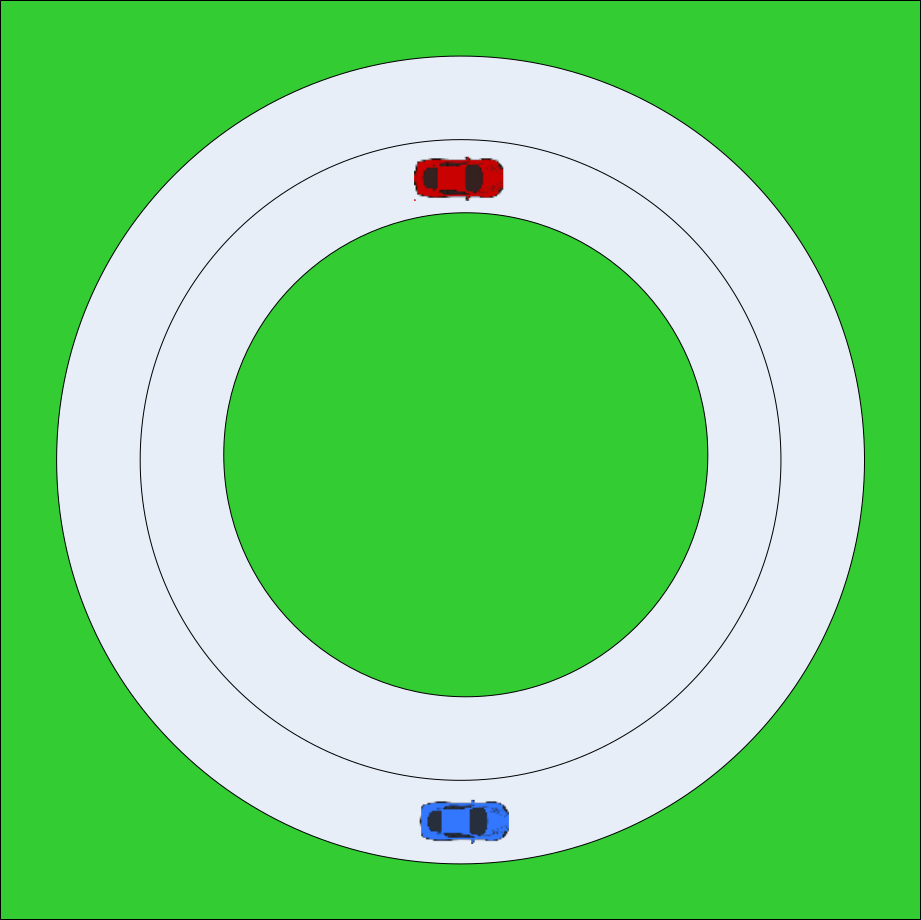

    3.1 Plot a transform representing the second car at [300,125], use the ‘X’ axis of the transform to represent the heading of the car, make transform red with length of 50. 

    3.2 Make the second car incrementally drives in the opposite direction to the first car 

    3.3 Determine the relative transform between the two cars at each time step 

## 4. Bonus: Consider a distance sensor mounted to the first car (blue) that is tracking the distance to the second car 

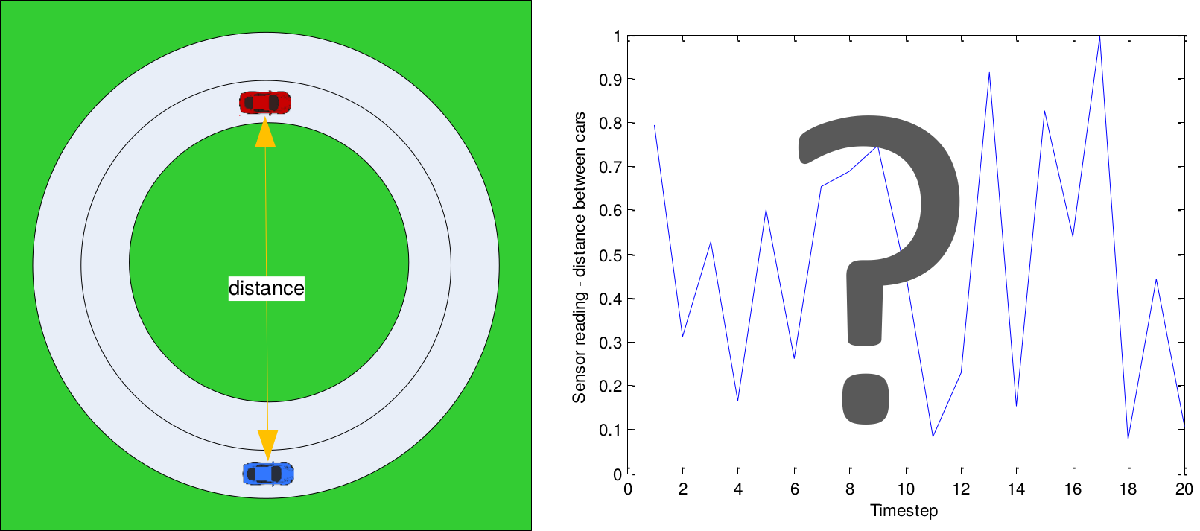

    4.1 Plot a graph of the distances between the two cars as they drive around the track